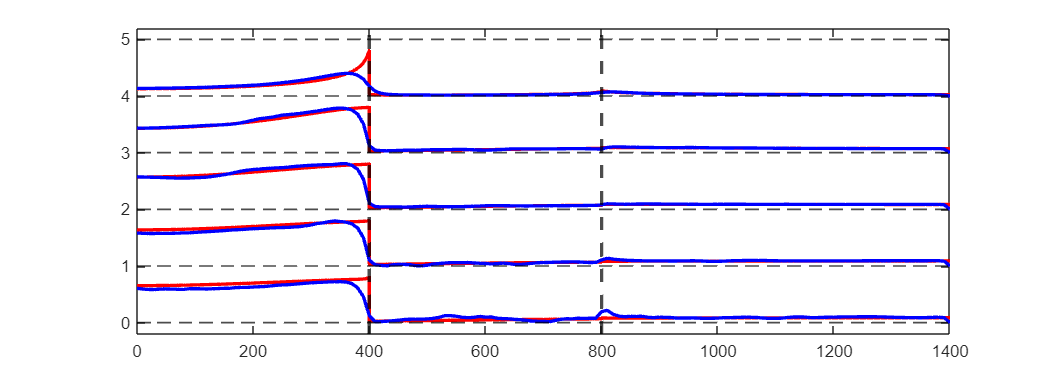

packing_ratio = 5;
Contraction = 50;
N = 50;
r_points = 101;
z_points_per_region = 101;
r_indices = [21, 41, 61, 81, 101];
dimensionless_r = (r_indices - 1)/100;

dimensionless_z = [linspace(0, L1/L, z_points_per_region), linspace(L1/L, L2/L, z_points_per_region), linspace(L2/L, 1, z_points_per_region)];
z_points = length(dimensionless_z);
thick_filament_half_spacing = (45/sqrt(3))*10^(-9);
thick_radius = 7e-9;
thin_radius = 5e-9;
L_thin = 1000e-9;
L_thick = 800e-9;
R = 500e-9;
D10 = 45e-9;
R_red = thick_radius / thick_filament_half_spacing;
R_blue = thin_radius / thick_filament_half_spacing;
Phi = [1 - 2*sqrt(3)*pi*(R_red^2/12); 1 - 2*sqrt(3)*pi*(packing_ratio*R_blue^2/12 + R_red^2/12); 1 - 2*sqrt(3)*pi*(packing_ratio*R_blue^2/12)];
U = 1000e-9;
L = L_thin + (1-Contraction/100)*L_thick;
L2 = L_thick;
L1 = (1-Contraction/100)*L_thick;
lambda = bessel_zeros(1:N);
bessel_values0 = besselj(0, (dimensionless_r.')*lambda);
bessel_values1 = besselj(1, (dimensionless_r.')*lambda);
if packing_ratio == 2
    fully_dimensionless_lateral_permeabilities = [0.1864, 0.0362, 0.0938];
    fully_dimensionless_axial_permeabilities = [0.3729, 0.0728, 0.2038];
    beta = 0.6175;
elseif packing_ratio == 3
    fully_dimensionless_lateral_permeabilities = [0.1864, 0.0212, 0.0435];
    fully_dimensionless_axial_permeabilities = [0.3729, 0.0433, 0.1071];
    beta = 0.7127;
elseif packing_ratio == 5
    fully_dimensionless_lateral_permeabilities = [0.1864, 0.00618, 0.00737];
    fully_dimensionless_axial_permeabilities = [0.3729, 0.0247, 0.0759];
    beta = 0.7238;
end
gamma = [0; beta; 1];
regions = [ones(1, z_points_per_region), 2*ones(1, z_points_per_region), 3*ones(1, z_points_per_region)];

Darcy_flux = calculate_velocity(N, thick_filament_half_spacing, Phi, fully_dimensionless_lateral_permeabilities, fully_dimensionless_axial_permeabilities, gamma, lambda, R, L, L1, L2, dimensionless_r, dimensionless_z, regions, bessel_values0, bessel_values1);
u_r_Darcy = Darcy_flux(:, :, 1)*((R/L)*1000e-9);
w_Darcy = Darcy_flux(:, :, 2)*(-1000e-9);
scaling_factors_u_r = 0.8*((1./max(abs(u_r_Darcy.'))).');
scaling_factors_w = 0.8*((1./max(abs(w_Darcy.'))).');
u_r_Darcy = scaling_factors_u_r.*u_r_Darcy;
w_Darcy = scaling_factors_w.*w_Darcy;

for k = 1:length(dimensionless_r)
    plot(dimensionless_z*L*1e9, (k-1) + u_r_Darcy(k, :), 'r', 'LineWidth', 2)
    hold on
    plot(linspace(0, L*1e9, length(radial_flux_comsol(1, :))), (k-1) + scaling_factors_u_r(k)*radial_flux_comsol(r_indices(k), :), 'b', 'LineWidth', 2)
    yline(k-1, '--k', 'LineWidth', 1)
end
yline(length(dimensionless_r), '--k', 'LineWidth', 1)
xline(L1*1e9, '--k', 'LineWidth', 2)
xline(L2*1e9, '--k', 'LineWidth', 2)
ylim([-0.2, length(dimensionless_r)+0.2])
x0=10;
y0=10;
width=300*(L/R);
height=300;
set(gcf,'position',[x0,y0,width,height])

function fluid_velocities = calculate_velocity(N, thick_filament_half_spacing, Phi, fully_dimensionless_lateral_permeabilities, fully_dimensionless_axial_permeabilities, gamma, lambda, R, L, L1, L2, r_Darcy, z_Darcy, regions, bessel_values0, bessel_values1)
    L1 = L1/L;
    L2 = L2/L;
    beta = gamma(2);

    k_perp_vector = (fully_dimensionless_lateral_permeabilities*thick_filament_half_spacing^2/R^2).';
    k_parallel_vector = (fully_dimensionless_axial_permeabilities*thick_filament_half_spacing^2/L^2).';
    G = zeros(3, N);

    for j = 1:3
        for n = 1:N
            G(j, n) = lambda(n)*sqrt(k_perp_vector(j)/k_parallel_vector(j));
        end
    end
    coefficients = zeros(6, N);
    
    for n = 1:N
        M = zeros(6, 6);
        M(1, 1) = exp(-G(1, n)*L1);
        M(1, 2) = -1;
        
        M(2, 5) = 1;
        M(2, 6) = -exp(-G(3, n)*(1-L2));
        
        M(3, 1) = k_parallel_vector(1)*G(1, n);
        M(3, 2) = -k_parallel_vector(1)*G(1, n)*exp(-G(1, n)*L1);
        M(3, 3) = -k_parallel_vector(2)*G(2, n)*exp(-G(2, n)*(L2-L1));
        M(3, 4) = k_parallel_vector(2)*G(2, n);
        
        M(4, 3) = k_parallel_vector(2)*G(2, n);
        M(4, 4) = -k_parallel_vector(2)*G(2, n)*exp(-G(2, n)*(L2-L1));
        M(4, 5) = -k_parallel_vector(3)*G(3, n)*exp(-G(3, n)*(1-L2));
        M(4, 6) = k_parallel_vector(3)*G(3, n);
        
        M(5, 1) = 1;
        M(5, 2) = exp(-G(1, n)*L1);
        M(5, 3) = -exp(-G(2, n)*(L2-L1));
        M(5, 4) = -1;
        
        M(6, 3) = 1;
        M(6, 4) = exp(-G(2, n)*(L2-L1));
        M(6, 5) = -exp(-G(3, n)*(1-L2));
        M(6, 6) = -1;
        
        v = zeros(6, 1);
        I_n = 2 / (lambda(n)*besselj(1, lambda(n)));
        v(3) = beta*Phi(2) + (1 - Phi(3));
        v(4) = Phi(3) - beta*Phi(2);
        v = v*I_n;
        
        coefficients(:, n) = linsolve(M, v);
    end
    
    A = [coefficients(1,:); coefficients(3,:); coefficients(5,:)];
    B = [coefficients(2,:); coefficients(4,:); coefficients(6,:)];

    u_r_Darcy = zeros(length(r_Darcy), length(z_Darcy));
    w_Darcy = zeros(length(r_Darcy), length(z_Darcy));
    for a = 1:length(r_Darcy)
        w_Darcy(a, :) = -gamma(regions).*Phi(regions);
    end
    L_vector = [0, L1, L2, 1];
    for n = 1:N
        u_r_Darcy = u_r_Darcy + bessel_values1(:, n)*(k_perp_vector(regions).*lambda(n).*(A(regions, n).*exp(G(regions, n).*(z_Darcy.' - L_vector(regions+1).')) + B(regions, n).*exp(-G(regions, n).*(z_Darcy.' - L_vector(regions).')))).';
        w_Darcy = w_Darcy - bessel_values0(:, n)*(k_parallel_vector(regions).*G(regions, n).*(A(regions, n).*exp(G(regions, n).*(z_Darcy.' - L_vector(regions+1).')) - B(regions, n).*exp(-G(regions, n).*(z_Darcy.' - L_vector(regions).')))).';
    end

    fluid_velocities = zeros(length(r_Darcy), length(z_Darcy), 2);
    fluid_velocities(:, :, 1) = u_r_Darcy;
    fluid_velocities(:, :, 2) = w_Darcy;

end